IDX = 2925

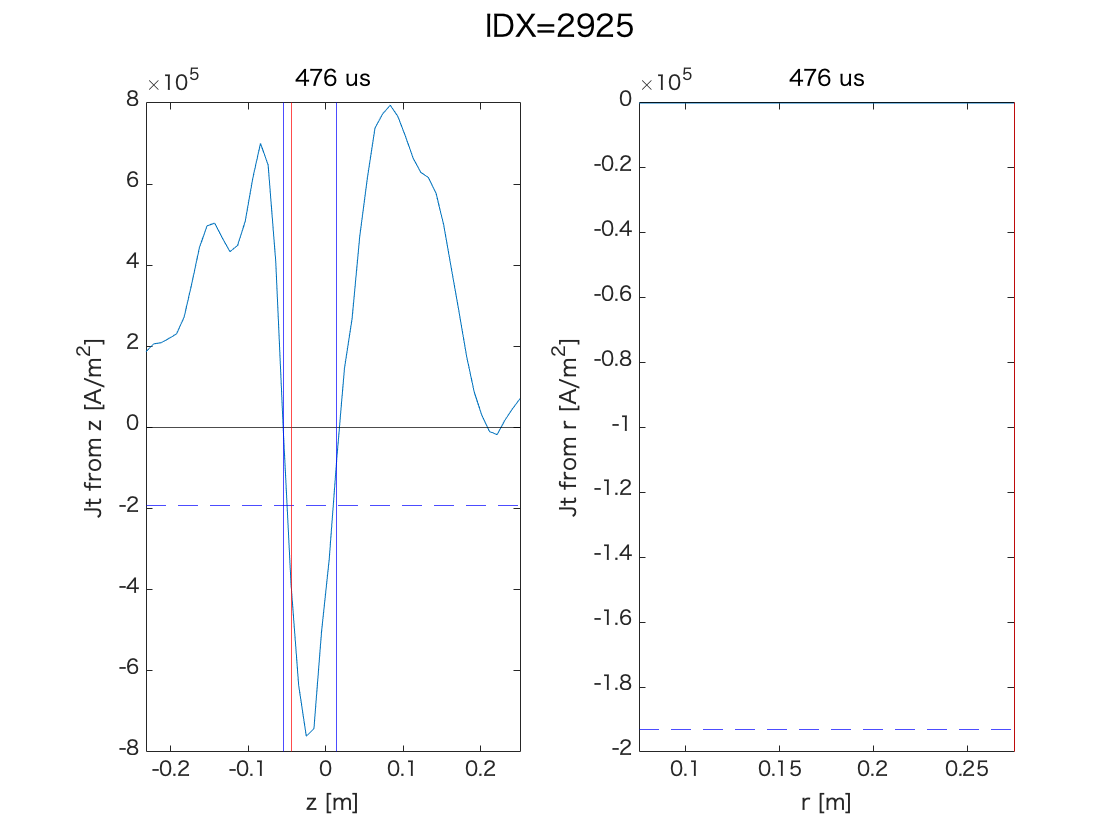

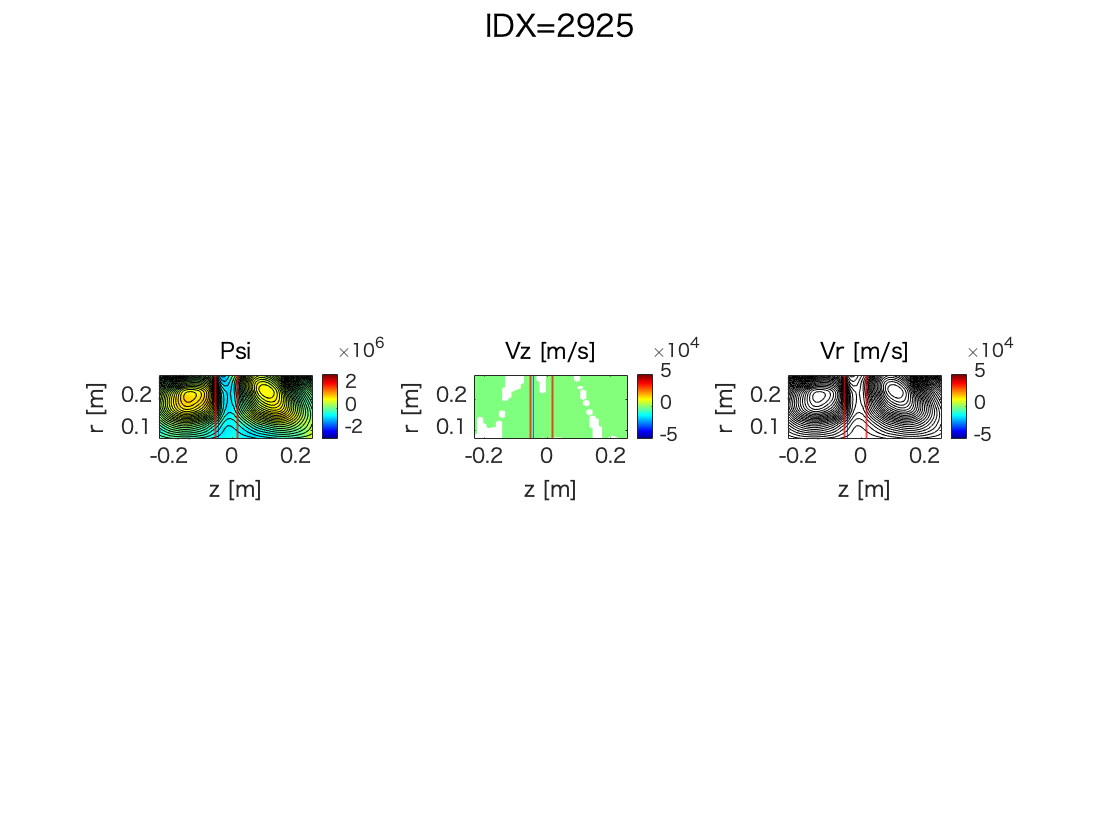

clearvars 
%-except wide xr

%%ファイルへのパスを作る
%それぞれのPCから共有フォルダまでのパスはそれぞれ異なるので各自で設定
pathname.ts3u=getenv('ts3u_path');%old-koalaのts-3uまでのパス
pathname.fourier=getenv('fourier_path');%md0までのpath
pathname.NIFS=getenv('NIFS_path');%resultsまでのpath
pathname.save=getenv('save_path');

DOCID='1wG5fBaiQ7-jOzOI-2pkPAeV6SDiHc_LrOdcbWlvhHBw';
T=getTS6log(DOCID);% ログのテーブルを取得
%  node='Crowbar_us_';  % 検索する列の名前. T.Properties.VariableNamesで一覧表示できる
%  pat=454;   % 検索パターン（数値なら一致検索、文字なら含む検索）　
% 
% subT=searchlog(T,node,pat);% ログのテーブルから当てはまるものを抽出した新しいテーブルを作成

% IDXlist=[2897 2906 2907 2912 2913];
% tcal=repmat([471 476],numel(IDXlist),1);

IDXlist=2925;
tcal=[476 484];


% IDXlist=[2911:2913 2925 2926 2927 2931 2933 2947:2950 2942 2943 2946];
% shot=struct('a',2911:2913,'b',[2925 2926 2927],'c',[2931 2933],'d',2947:2950,'e',[2942 2943 2946]);
% IDXlist=shot.a; %【input】テーブルから解析したいshot番号を抽出して入力
%(a)211223/IDX2870:2920(42:44)/2911:2913/dtacq3592:3594
%(b)211224/IDX2922:2950(4,5,8)/2925,2926,2927/dtacq3606,3607,3609
%(c)211224/IDX2922:2950(10,12)/2931,2933/dtacq3611,3613
%(d)211224/IDX2922:2950(26:29)/2947:2950/dtacq3626-3629
%(e)211224/IDX2922:2950(21,22,25)/2942,2943,2946/dtacq3621,3622,3625

% tcal=[472 478; 474 479; 474 481; 
%     476 484; 476 482; 476 483; 
%     485 499; 485 499;
%     475 483; 474 483; 473 483; 479 489;
%     485 496; 484 494; 483 495]; %15*2

wide=zeros(numel(IDXlist),1); %電流シートの半値幅
xr=zeros(numel(IDXlist),1);
Vzl=zeros(numel(IDXlist),1);
Vzr=zeros(numel(IDXlist),1);

for i=1:numel(IDXlist)
    IDX=IDXlist(i)
    tstart=tcal(i,1);
    tend=tcal(i,2);
    [wide(i),xr(i),Vzl(i),Vzr(i)]=jtsheetcalc(T, IDX, pathname, tstart, tend);
end


% %X点でのBt
% Bt_xa=45*4e+3*1.256*10^-6/mean(xr(1:3))/2/pi;
% Bt_xb=45*4e+3*1.256*10^-6/mean(xr(4:6))/2/pi;
% Bt_xc=45*4e+3*1.256*10^-6/mean(xr(7:8))/2/pi;
% Bt_xd=45*4e+3*1.256*10^-6/mean(xr(9:12))/2/pi;
% Bt_xe=45*4e+3*1.256*10^-6/mean(xr(13:15))/2/pi;
% 
% Group=["a";"b";"c";"d";"e"];
% Xposition=[mean(xr(1:3));mean(xr(4:6));mean(xr(7:8));mean(xr(9:12));mean(xr(13:15))];
% Sheet_width=[mean(wide(1:3));mean(wide(4:6));mean(wide(7:8));mean(wide(9:12));mean(wide(13:15))];
% Vz_left=[mean(Vzl(1:3));mean(Vzl(4:6));mean(Vzl(7:8));mean(Vzl(9:12));mean(Vzl(13:15))];
% Vz_right=[mean(Vzr(1:3));mean(Vzr(4:6));mean(Vzr(7:8));mean(Vzr(9:12));mean(Vzr(13:15))];
% Bt_x=[Bt_xa;Bt_xb;Bt_xc;Bt_xd;Bt_xe];
% dataset=table(Group,Xposition,Sheet_width,Vz_left,Vz_right,Bt_x)
% 
% figure
% h=scatter(-Vz_right,Vz_left,[],'red');
% xlabel('|Vz| (right) [m/s]')
% ylabel('|Vz| (left)  [m/s]')
% str={'a','b','c','d','e'};
% text(-Vz_right,Vz_left,str)
% xlim([2e+3 11e+3])
% ylim([2e+3 11e+3])
% % xとyの表示範囲を取得
% x_lim = h.Parent.XLim;
% y_lim = h.Parent.YLim;
% hold on;
% % 対角線の描画
% plot(x_lim, y_lim);
% % 描画範囲の調節
% % xlim(h.Parent.XLim)
% % ylim(h.Parent.YLim)
% hold off;

% wide_a=mean(wide(1:3))
% wide_b=mean(wide(4:6))
% wide_c=mean(wide(7:8))
% wide_d=mean(wide(9:12))
% wide_e=mean(wide(13:15))
% 
% xr_a=mean(xr(1:3))
% xr_b=mean(xr(4:6))
% xr_c=mean(xr(7:8))
% xr_d=mean(xr(9:12))
% xr_e=mean(xr(13:15))
% 
% Vzl_a=mean(Vzl(1:3))
% Vzl_b=mean(Vzl(4:6))
% Vzl_c=mean(Vzl(7:8))
% Vzl_d=mean(Vzl(9:12))
% Vzl_e=mean(Vzl(13:15))
% 
% Vzr_a=mean(Vzr(1:3))
% Vzr_b=mean(Vzr(4:6))
% Vzr_c=mean(Vzr(7:8))
% Vzr_d=mean(Vzr(9:12))
% Vzr_e=mean(Vzr(13:15))


function rgwdata = importfile(filename, dataLines)
%IMPORTFILE テキスト ファイルからデータをインポート
%  UNTITLED = IMPORTFILE(FILENAME) は既定の選択に関してテキスト ファイル FILENAME
%  からデータを読み取ります。  データを table として返します。
%
%  UNTITLED = IMPORTFILE(FILE, DATALINES) はテキスト ファイル FILENAME
%  の指定された行区間のデータを読み取ります。DATALINES
%  を正の整数スカラーとして指定するか、行区間が不連続の場合は正の整数スカラーからなる N 行 2 列の配列として指定します。
%
%  例:
%  Untitled = importfile("X:\results\ts-3u\211222\211222006.rgw", [1, Inf]);
%
%  READTABLE も参照してください。
%
% MATLAB からの自動生成日: 2022/01/15 13:57:51

%% 入力の取り扱い

% dataLines が指定されていない場合、既定値を定義します
if nargin < 2
    dataLines = [1, Inf];
end

%% インポート オプションの設定およびデータのインポート
opts = delimitedTextImportOptions("NumVariables", 18);

% 範囲と区切り記号の指定
opts.DataLines = dataLines;
opts.Delimiter = "\t";

% 列名と型の指定
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "ch6", "ch7", "ch8", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18"];
opts.SelectedVariableNames = ["ch6", "ch7", "ch8"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "double", "double", "double", "string", "string", "string", "string", "string", "string", "string", "string"];

% ファイル レベルのプロパティを指定
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 変数プロパティを指定
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var11", "Var12", "Var13", "Var14", "Var15", "Var16", "Var17", "Var18"], "EmptyFieldRule", "auto");

% データのインポート
rgwdata = readtable(filename, opts);

end

function [wide,xr,Vzl,Vzr]=jtsheetcalc(T, IDX, pathname, tstart, tend)
date=T.date(IDX);
shot=T.shot(IDX);
TF_shot=T.TFoffset(IDX);
d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);
offset_TF=isfinite(TF_shot);
%start=T.Period_StartTime_(IDX);
if isnan(T.EF_A_(IDX))
    i_EF=150;
else  
    i_EF=T.EF_A_(IDX);
end

trange = tstart:tend;
frame=tend-tstart+1;
column = ceil(sqrt(frame)); 
row = ceil(frame/column);

[B_z,r_probe,z_probe,ch_dist,data,data_raw,shot_num]= get_B_z(date,TF_shot,shot,offset_TF,i_EF,pathname.ts3u);
B_z = B_z([2,3,4,6,7,8],2:end,:);
data = data([2,3,4,6,7,8],2:end,:);
z_probe = z_probe(2:end);
ch_dist = ch_dist([2,3,4,6,7,8],2:end);
r_probe = r_probe([2,3,4,6,7,8]);

layer_num = 30;

%fixed_Clayer=true
max_psi_color = 0.0400;
min_psi_color = -0.0200;
layer_resolution = 0.0002;
contour_layer =  min_psi_color:layer_resolution:max_psi_color;

%fitting=true
z_space = linspace(z_probe(1),z_probe(end),50);
r_space = linspace(r_probe(1),r_probe(end),50);
[psi_mesh_z,psi_mesh_r] = meshgrid(z_space,r_space);

psi_store = zeros(length(r_space),length(z_space),length(trange));
color_store = psi_store;
Et_store = psi_store;
Br_store = psi_store;
Jt_store = psi_store;

for i = trange    
        for j = 1:size(B_z,1)
            psi(j,:) = smooth(z_probe,B_z(j,:,i),'lowess');
        end
        for j = 1:size(B_z,2)
            psi(:,j) = smooth(r_probe,B_z(:,j,i),'lowess');
        end
        
        psi = get_psi(B_z,r_probe,i);
        
        psi_store(:,:,i) = griddata(z_probe,r_probe,psi,psi_mesh_z,psi_mesh_r,'cubic');
        
        
        for j = 1:size(psi_store(:,:,i),1)
            psi_store(j,:,i) = smooth(z_space,psi_store(j,:,i),'lowess');
        end
        for j = 1:size(psi_store(:,:,i),2)
            psi_store(:,j,i) = smooth(z_space,psi_store(:,j,i),'lowess');
        end
            
        %show_jt=true
        [j_t,z_space_jt,r_space_jt] = jt(B_z,z_probe,r_probe,i);
        Jt_store(:,:,i) = griddata(z_space_jt,r_space_jt,j_t,psi_mesh_z,psi_mesh_r,'v4');
        color_store(:,:,i) = griddata(z_space_jt,r_space_jt,j_t,psi_mesh_z,psi_mesh_r,'v4');
       
        E_t = Et(B_z,r_probe,i);
        Et_store(:,:,i) = griddata(z_probe,r_probe,E_t,psi_mesh_z,psi_mesh_r,'v4');
        Br_store(:,:,i) = Br(psi_store(:,:,i),z_space,r_space);
        Bz_store(:,:,i) = griddata(z_probe,r_probe,B_z(:,:,i),psi_mesh_z,psi_mesh_r,'v4');
        
end

[max_psi,max_psi_r]=max(psi_store,[],1);
max_psi=squeeze(max_psi);
%plot(max_psi)

%%%midplaneとかO点、X点を探す
n=50;
[psimid,mid]=min(psi_store(:,20:30,:),[],2);
[opoint,~]=islocalmin(psimid,1);
[xpoint,~]=islocalmax(psimid,1);
[xp_psi,maxxp]=max(squeeze(psimid),[],1);
r_index=1:n;

mid=mid+19;

% psi_store(:,:,476)
% mid(:,:,476)
% opoint(:,:,476)
% xpoint(:,:,476)
% maxxp(:,476)

%%%z方向視線からのJt
Jt_fromz=zeros(frame,n);
xJt=zeros(frame,1);
for i=1:frame
    if sum(maxxp(:,i))>0
        r_maxxp=r_index(maxxp(:,i));
        r_s=max(1,r_maxxp-15);
        r_n=min(n,r_maxxp+15);
        for j=1:n
            Jt_fromz(i,j)=sum(Jt_store(r_s:r_n,j,i+tstart-1))/(r_n-r_s+1);            
        end
    end
    %各時刻でのz方向視線からのJtのプロット
%     subplot(row,column,i);
%     plot(psi_mesh_z(1,:),Jt_fromz(i,:))
%     yline(0,'b-')
%     xline(psi_mesh_z(1,squeeze(mid(maxxp(:,i),:,i))),'r-')
%     ylim([-3e+6 3e+6])
%     title(string(trange(i))+' us')
%     xlabel('z [m]')
%     ylabel('Jt from z [A/m^{2}]')
    
    xJt(i,1)=Jt_fromz(i,squeeze(mid(maxxp(:,i),:,i)));
end

%X点でのJtが最小の時刻
[xJt_min,tmin]=min(xJt);

%半値の交点がぴったり2点の場合に半値幅を求める（交点が2個以外を考慮したverも作りたい）
lind=0;
rind=0;
for j=1:squeeze(mid(maxxp(:,tmin)))
    if (Jt_fromz(tmin,j)-xJt_min*0.5)*(Jt_fromz(tmin,j+1)-xJt_min*0.5)<=0
        if abs(Jt_fromz(tmin,j)-xJt_min*0.5)<abs(Jt_fromz(tmin,j+1)-xJt_min*0.5)
            lind=j;
            sheet_left=psi_mesh_z(1,j);
        else
            lind=j+1;
            sheet_left=psi_mesh_z(1,j+1);
        end  
    end
end

for j=squeeze(mid(maxxp(:,tmin))):n-1
    if (Jt_fromz(tmin,j)-xJt_min*0.5)*(Jt_fromz(tmin,j+1)-xJt_min*0.5)<=0
        if abs(Jt_fromz(tmin,j)-xJt_min*0.5)<abs(Jt_fromz(tmin,j+1)-xJt_min*0.5)
            rind=j;
            sheet_right=psi_mesh_r(1,j);
        else
            rind=j+1;
            sheet_right=psi_mesh_z(1,j+1);
        end  
    end
end

%[[output]]
wide=sheet_right-sheet_left;
xr=r_space_jt(maxxp(:,tmin),1);
%x_z=grid2D.zq(1,squeeze(mid(maxxp(:,tmin)

%X点でのJtのプロット
% figure
% plot(tstart:tend, xJt)
% xlabel('Time [us]')
% ylabel('Jt at Xpoint[A/m^{2}]')

%電流シート高さLの定義
Jt_fromr=zeros(n,1);
for j=1:n
    Jt_fromr(j,1)=sum(Jt_store(j,lind:rind))/(rind-lind+1);            
end
%xJt_r=Jt_fromr(r_maxxp,1);

%速度Vの各成分を計算
% Vz=zeros(size(grid2D.rq,1),size(grid2D.rq,2));
% Vr=zeros(size(grid2D.rq,1),size(grid2D.rq,2));
Vz(:,:)=Et_store(:,:,tmin+tstart-1)./Br_store(:,:,tmin+tstart-1);
Vr(:,:)=-Et_store(:,:,tmin+tstart-1)./Bz_store(:,:,tmin+tstart-1);
%vが大きすぎるところを外れ値検索で外す
vzind=isoutlier(Vz,'median',1);
Vz(vzind)=NaN;
vrind=isoutlier(Vr,'median',1);
Vr(vrind)=NaN;
clear vzind vrind
Vz(abs(Vz) > 10*1e+4) = NaN;
Vr(abs(Vr) > 10*1e+4) = NaN;

%%%z方向視線からのVz
%NaNが含まれる場合は対応していない
L_s=max(1,r_maxxp-5);
L_n=min(n,r_maxxp+5);
%[[output]]
Vzl=sum(Vz(L_s:L_n,lind-5:lind-1),'all')/(5*(L_n-L_s+1));
Vzr=sum(Vz(L_s:L_n,rind+1:rind+5),'all')/(5*(L_n-L_s+1));
%Vz(L_s:L_n,rind+1:rind+5)

%plot

% %X点でのJtが最小の時刻でのz方向視線からのJtのプロット
% figure('Position', [0 0 1000 500],'visible','on');
figure
subplot(1,2,1)
plot(psi_mesh_z(1,:),Jt_fromz(tmin,:))
xlim([psi_mesh_z(1,1) psi_mesh_z(1,n)])
yline(0,'k-')
yline(xJt_min*0.5,'b--') %半値幅
xline(psi_mesh_z(1,squeeze(mid(maxxp(:,tmin),:,tmin))),'r-')
xline(sheet_left,'b-')
xline(sheet_right,'b-')
title(string(trange(tmin))+' us')
xlabel('z [m]')
ylabel('Jt from z [A/m^{2}]')

%tminでのr方向視線からのJtのプロット
%figure
subplot(1,2,2)
plot(psi_mesh_r(:,1),Jt_fromr)
xlim([psi_mesh_r(n,1) psi_mesh_r(1,1)])
yline(0,'k-')
xline(xr,'r-')
% yline(xJt_r*0.5,'b--') %r方向視線での半値幅
yline(xJt_min*0.5,'b--') %z方向視線での半値幅
title(string(trange(tmin))+' us')
xlabel('r [m]')
ylabel('Jt from r [A/m^{2}]')

sgtitle(strcat('IDX=',num2str(IDX)))

% saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'Jtplot.png'))
% close
   
%磁気面のプロット
min_color = min(color_store(:));
max_color = max(color_store(:));
contour_layer_color =  min_color:(max_color-min_color)/50:max_color;
%figure('Position', [0 0 1000 500],'visible','on');
figure
%f=figure;
%f.WindowState = 'maximized';
subplot(1,3,1)
contourf(psi_mesh_z,psi_mesh_r,color_store(:,:,tmin+tstart-1),contour_layer_color,'LineStyle','none');
%contourf(psi_mesh_z,psi_mesh_r,psi_store(:,:,tmin+tstart-1),contour_layer,'Fill','on');
colormap(jet)
axis image
axis tight manual
caxis([-2.7*1e+6,3*1e+6]) %カラーバーの軸の範囲
%caxis([-maxrange,maxrange])
colorbar('Location','eastoutside')
hold on
plot(psi_mesh_z(1,squeeze(mid(:,:,tmin))),psi_mesh_r(:,1))
contour(psi_mesh_z(1,:),psi_mesh_r(:,1),squeeze(psi_store(:,:,tmin+tstart-1)),35,'black')
plot(psi_mesh_z(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),psi_mesh_r(opoint(:,:,tmin),1),"ro")
plot(psi_mesh_z(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),psi_mesh_r(xpoint(:,:,tmin),1),"rx")
xline(sheet_left,'r-','LineWidth',1)
xline(sheet_right,'r-','LineWidth',1)
hold off
title('Psi')
xlabel('z [m]')
ylabel('r [m]')

subplot(1,3,2)
contourf(psi_mesh_z(1,:),psi_mesh_r(:,1),Vz(:,:),20,'LineStyle','none')
colormap(jet)
axis image
axis tight manual
caxis([-5*1e+4,5*1e+4])
colorbar('Location','eastoutside')
hold on
plot(psi_mesh_z(1,squeeze(mid(:,:,tmin))),psi_mesh_r(:,1))
contour(psi_mesh_z(1,:),psi_mesh_r(:,1),squeeze(psi_store(:,:,tmin)),35,'black')
plot(psi_mesh_z(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),psi_mesh_r(opoint(:,:,tmin),1),"ro")
plot(psi_mesh_z(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),psi_mesh_r(xpoint(:,:,tmin),1),"rx")
xline(sheet_left,'r-','LineWidth',1)
xline(sheet_right,'r-','LineWidth',1)
hold off
title('Vz [m/s]')
xlabel('z [m]')
ylabel('r [m]')

subplot(1,3,3)
contourf(psi_mesh_z(1,:),psi_mesh_r(:,1),Vr(:,:),20,'LineStyle','none')
colormap(jet)
axis image
axis tight manual
caxis([-5*1e+4,5*1e+4])
colorbar('Location','eastoutside')
hold on
plot(psi_mesh_z(1,squeeze(mid(:,:,tmin))),psi_mesh_r(:,1))
contour(psi_mesh_z(1,:),psi_mesh_r(:,1),squeeze(psi_store(:,:,tmin+tstart-1)),35,'black')
plot(psi_mesh_z(1,squeeze(mid(opoint(:,:,tmin),:,tmin))),psi_mesh_r(opoint(:,:,tmin),1),"ro")
plot(psi_mesh_z(1,squeeze(mid(xpoint(:,:,tmin),:,tmin))),psi_mesh_r(xpoint(:,:,tmin),1),"rx")
xline(sheet_left,'r-','LineWidth',1)
xline(sheet_right,'r-','LineWidth',1)
hold off
title('Vr [m/s]')
xlabel('z [m]')
ylabel('r [m]')

sgtitle(strcat('IDX=',num2str(IDX)))

% saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'vplot.png'))
% close

end
